# Giunto 1 

# GRUPPO G

- Fares Peter William Guirguis - mat.721654

- Mirandola Edoardo - mat. 723993

- Pennacchio Manuele - mat. 721965

# Inizializzazione del programma

clear all;
close all;
clc;
Group_name = 'GruppoG';
addpath("..\modelli\")
addpath("..\file_mat_init\")

# Inizializzazione del Sistema

model=ElasticRoboticSystem();
model.show;

This system has 4 outputs:
- position_1
- position_2
- velocity_1
- velocity_2
This system has 2 inputs:
- torque_1, with maximum limit = 600.000000
- torque_2, with maximum limit = 600.000000



% visualizzazione output del sistema
output_number=model.getOutputNumber 

output_number = 4

for i=1:output_number
    fprintf('Output %d:    %s\n',i,model.getOutputName{i});
end

Output 1:    position_1
Output 2:    position_2
Output 3:    velocity_1
Output 4:    velocity_2



% visualizzazione sampling time
st=model.getSamplingPeriod;

# Risposta in frequenza del sistema

Il sistema in esame simula un robot SCARA. Ogni giunto può essere modellizzato come un sistema motore-trasmissione-carico con:

- trasmissione elastica

- attrito statico

Il metodo utilizzato per l'identificazione è il chirp in closed-loop, ossia l'applicazione di una successione di frequenze entro un intervallo predefinito

Considerando che l'attrito statico potrebbe generare problemi di identificazione a causa del continuo passaggio nei punti di velocità nulla, il segnale di eccitazione è composto da:

- **chirp**: segnale con frequenza variabile nel tempo entro intervalli predefiniti

- **portante**: segnale con frequenza costante utilizzato per diminuire l'effetto dell'attrito statico in fase di identificazione

## Controllore in cascata per l'identificazione in close-loop

% sistema + controllore
cs=ControlledSystemScara(model,Group_name);
% controllo del giunto 1
Kp_g1 = 0.01;
Ki_g1 = 0.1;
% controllo del giunto 2
Kp_g2 = 0.01;
Ki_g2 = 0.1;
ctrl = ScaraBasicPIController(st, Kp_g1, Ki_g1, Kp_g2, Ki_g2);

% impostazione della coppia massima
ctrl.setUMax(model.getUMax);

% impostazione della isatanza del controllore
cs.setController(ctrl);

## Segnale di eccitazione composto da portante + chirp

la durata del segnale dovrebbe essere di almeno un periodo 

#### Portante

% parametri della portante
omega_portante = 1;%[rad/s]
ampiezza_portante= 250;%[Nm]
T_portante=2*pi/omega_portante;
%vettore tempo (> T_portante)
t=(0:st:(1.1*T_portante))';

portante=ampiezza_portante*sin(omega_portante*t);

#### Chirp

ampliezza_identificazione= 250;%[Nm]
% frequenza minima
w0=omega_portante*10; %[rad/s]
% frequenza massima
w1=pi/st; %[rad/s]

chrip_id = ampliezza_identificazione*chirp(t,w0/2/pi,t(end),w1/2/pi,'logarithmic');

#### Azione di controllo = portante + chirp

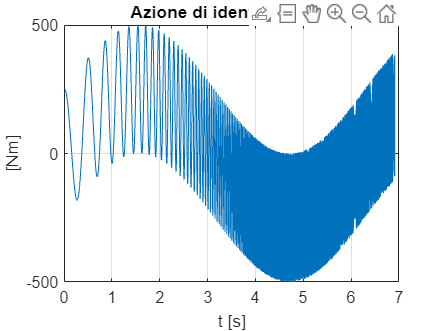

control_action = portante + chrip_id;

% grafico del segnale di eccitazione
figure();
plot(t,control_action)
xlabel('t [s]')
ylabel('[Nm]')
title('Azione di identificazione')
grid on

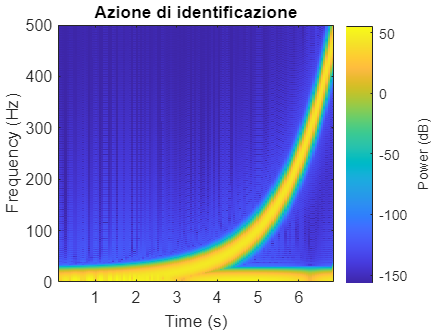

%spettrogramma del segnale di eccitazione
figure()
pspectrum(control_action,1/st,'spectrogram'); 
title('Azione di identificazione')


%riferimento
reference = zeros(length(t),model.getOutputNumber);

#### giunto 1

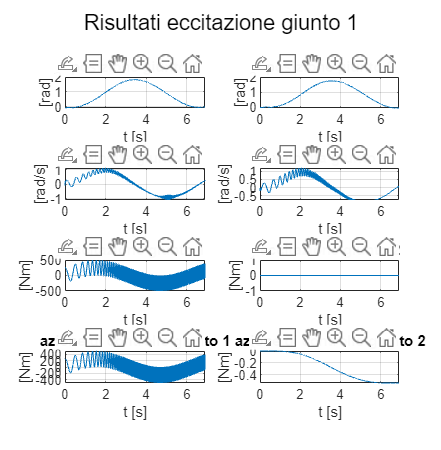

% creazione del segnale di eccitazione al giunto 1
exciting_signal_g1 = zeros(length(t),model.getInputNumber);
exciting_signal_g1(:,1) = control_action;
cs.initialize;
% applico il segnale di eccitazione al giunto 1
for idx=1:length(t)
    [process_output_g1(idx,:),control_action_g1(idx,:),t_g1(idx,1)]=cs.step(reference(idx,:)',exciting_signal_g1(idx,:)');  
end

%grafici
figure();
subplot(4,2,1)
plot(t_g1,process_output_g1(:,1))
xlabel('t [s]')
ylabel('[rad]')
title('posizione giunto 1')
xlim([t(1) t(end)])
grid on

subplot(4,2,3)
plot(t_g1,process_output_g1(:,3))
xlabel('t [s]')
ylabel('[rad/s]')
title('velocità giunto 1')
xlim([t(1) t(end)])
grid on

subplot(4,2,5)
plot(t_g1,exciting_signal_g1(:,1))
xlabel('t [s]')
ylabel('[Nm]')
title('eccitazione giunto 1')
xlim([t(1) t(end)])
grid on

subplot(4,2,7)
plot(t_g1,control_action_g1(:,1))
xlabel('t [s]')
ylabel('[Nm]')
title('azione di controllo giunto 1')
xlim([t(1) t(end)])
grid on

subplot(4,2,2)
plot(t_g1,process_output_g1(:,2))
xlabel('t [s]')
ylabel('[rad]')
title('posizione giunto 2')
xlim([t(1) t(end)])
grid on

subplot(4,2,4)
plot(t_g1,process_output_g1(:,4))
xlabel('t [s]')
ylabel('[rad/s]')
title('velocità giunto 2')
xlim([t(1) t(end)])
grid on

subplot(4,2,6)
plot(t_g1,exciting_signal_g1(:,2))
xlabel('t [s]')
ylabel('[Nm]')
title('eccitazione giunto 2')
xlim([t(1) t(end)])
grid on

subplot(4,2,8)
plot(t_g1,control_action_g1(:,2))
xlabel('t [s]')
ylabel('[Nm]')
title('azione di controllo giunto 2')
xlim([t(1) t(end)])
grid on

sgtitle('Risultati eccitazione giunto 1');
pos = get(gcf, 'Position');
set(gcf, 'Position',pos+[0 -200 0 150])

## Risposta in frequenza

#### Giunto 1

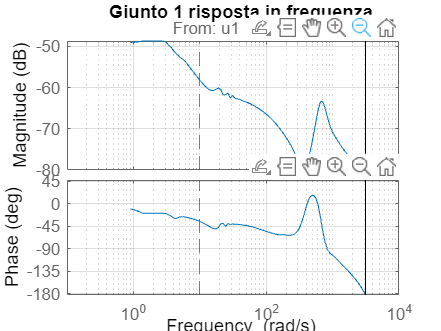

% modello giunto 1
identification_g1 = iddata(process_output_g1(:,3),control_action_g1(:,1),st);
frequency_response_identification_g1 = spafdr(identification_g1);
% diagramma di Bode giunto 1
figure();
subplot(1,1,1)
bode(frequency_response_identification_g1)
hold on
h1 = get(gcf,'Children');
xline(h1(3),w0,'--r')
xline(h1(2),w0,'--r')
hold off
grid on
title('Giunto 1 risposta in frequenza');

# Identificazione

il peso sulle frequenze consente la selezione delle frequenze più importanti per la stima del modello in quanto corrispondenti a quelle di lavoro

#### Modello del giunto 1  Terzo rodine

range di frequenze di rilevanza tra 100 rad/s e 1000 rad/s

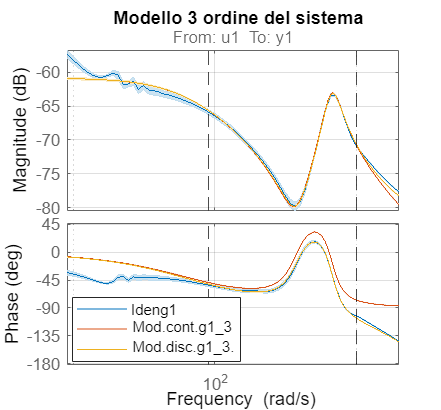

weight1_1 = 90;%rad/s
weight1_2 = 1000;%rad/s
peso = ones(length(frequency_response_identification_g1.Frequency),1);
% diminuzione del peso per per w<w1 e per w>w2
peso(frequency_response_identification_g1.Frequency<weight1_1) = 1e-3;
peso(frequency_response_identification_g1.Frequency>weight1_2) = 1e-3; 

% ottimizzazione della funzione di costo
opts = ssestOptions('WeightingFilter', peso, 'EnforceStability', 1);
% stima del modello come di ordine 3
modello_continuo_g1_3rd = ssest(frequency_response_identification_g1, 3, opts);
modello_discreto_g1_3rd = ssest(frequency_response_identification_g1, 3, 'Ts', st, opts);
% diagramma di Bode
figure();
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h = bodeplot(frequency_response_identification_g1, bode_opts);
hold on
showConfidence(h,3)
bode(modello_continuo_g1_3rd,modello_discreto_g1_3rd, bode_opts)

% plot linee di delimitazione delle frequenze di interesse
h1 = get(gcf,'Children');
xline(h1(3),weight1_1,'--k')
xline(h1(3),weight1_2,'--k')
xline(h1(2),weight1_1,'--k')
xline(h1(2),weight1_2,'--k')
hold off;
title("Modello 3 ordine del sistema ")
grid on
xlim([weight1_1/10 weight1_2*2])
set(gcf, 'Position',pos+[0 -100 0 100])
legend('Ideng1','Mod.cont.g1_3','Mod.disc.g1_3.','Location','best')

#### Modello del giunto 1  quinto ordine

range di frequenze di rilevanza tra 100 rad/s e 1000 rad/s

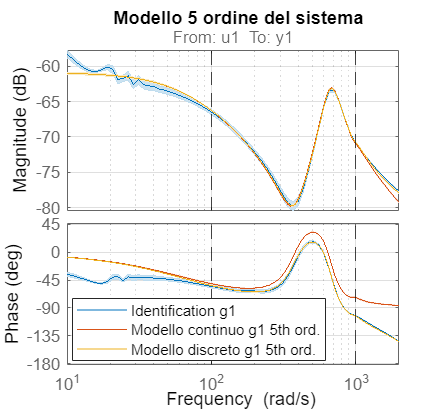

weight1_1 = 100;%rad/s
weight1_2 = 1000;%rad/s
peso = ones(length(frequency_response_identification_g1.Frequency),1);
% diminuzione del peso per per w<w1 e per w>w2
peso(frequency_response_identification_g1.Frequency<weight1_1) = 1e-3;
peso(frequency_response_identification_g1.Frequency>weight1_2) = 1e-3; 

% ottimizzazione della funzione di costo
opts = ssestOptions('WeightingFilter', peso, 'EnforceStability', 1);
% stima del modello come di ordine 3
modello_continuo_g1_5th = ssest(frequency_response_identification_g1, 5, opts);
modello_discreto_g1_5th = ssest(frequency_response_identification_g1, 5, 'Ts', st, opts);
% diagramma di Bode
figure();
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h = bodeplot(frequency_response_identification_g1, bode_opts);
hold on
showConfidence(h,3)
bode(modello_continuo_g1_5th,modello_discreto_g1_5th, bode_opts)

% plot linee di delimitazione delle frequenze di interesse
h1 = get(gcf,'Children');
xline(h1(3),weight1_1,'--k')
xline(h1(3),weight1_2,'--k')
xline(h1(2),weight1_1,'--k')
xline(h1(2),weight1_2,'--k')
hold off;

grid on
title("Modello 5 ordine del sistema ")
xlim([weight1_1/10 weight1_2*2])
set(gcf, 'Position',pos+[0 -100 0 100])
legend('Identification g1','Modello continuo g1 5th ord.','Modello discreto g1 5th ord.','Location','best')

### Modello del giunto 1  terzo ordine Vs quinto ordine

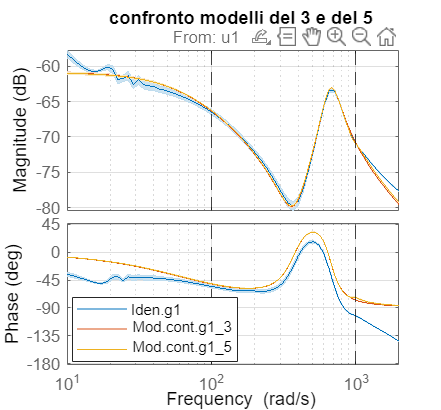

figure();
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h = bodeplot(frequency_response_identification_g1, bode_opts);
hold on
showConfidence(h,3)
bode(modello_continuo_g1_3rd,modello_continuo_g1_5th, bode_opts)

% plot linee di delimitazione delle frequenze di interesse
h1 = get(gcf,'Children');
xline(h1(3),weight1_1,'--k')
xline(h1(3),weight1_2,'--k')
xline(h1(2),weight1_1,'--k')
xline(h1(2),weight1_2,'--k')
hold off;

grid on
title("confronto modelli del 3 e del 5")
xlim([weight1_1/10 weight1_2*2])
set(gcf, 'Position',pos+[0 -100 0 100])
legend('Iden.g1','Mod.cont.g1_3','Mod.cont.g1_5','Location','best')

# Validazione

Per la fase di validazione, è stato scelto un segnale composto da una chirp e una portante, utilizzando parametri diversi rispetto al caso precedente. Combinando la chirp e la portante nel segnale composto, è possibile stimolare il sistema e verificare la sua risposta in condizioni diverse da quelle utilizzate per l'identificazine.

Si noti che durante la fase di validazione la portante prende la forma di un coseno e che il segnale di chirp assume una distribuzione quadratica in frequenza

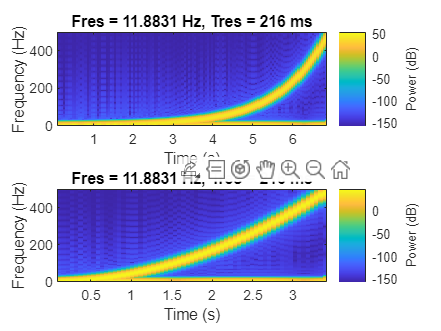

% parametri di validazione
ampliezza_validazione = 300;%[Nm]
omega_portante_validation = 2;%[rad/s]
ampiezza_portante_validation = 130;%[Nm]

% portante di validazione
T_portante_val=2*pi/omega_portante_validation;  %[s]
t_val=(0:st:(1.1*T_portante_val))';
portante_v=ampiezza_portante_validation*sin(omega_portante_validation*t_val);
% chirp di validazione
w0_v=omega_portante_validation*10; %[rad/s]
w1_v=pi/st; %[rad/s]
chrip_val = chirp(t_val,w0_v/2/pi,t_val(end),w1_v/2/pi, 'quadratic')*ampliezza_validazione;
% eccitazione di validazione
control_action_validation = portante_v + chrip_val;

% plot delle azioni di identificazione e di validazione
figure();
% spettrogramma dell'azione di identificazione
subplot(2,1,1)
subtitle("Identificazione")
pspectrum(control_action,1/st,'spectrogram');
% spettrogramma dell'azione di validazione
subplot(2,1,2)
subtitle("Validazione")
pspectrum(control_action_validation,1/st,'spectrogram');

#### Validazione del giunto 1

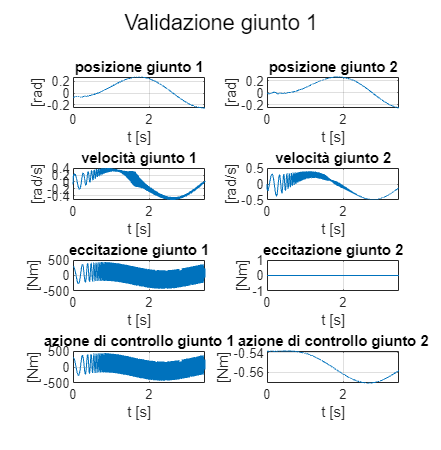

% segnale di validazione g1
exciting_signal_g1_validation = zeros(length(t_val),model.getInputNumber);
exciting_signal_g1_validation(:,1) = control_action_validation;

cs.initialize 
for idx=1:length(t_val)
    [process_output_g1_validation(idx,:),control_action_g1_validation(idx,:),t_g1_validation(idx,1)]=cs.step(reference(idx,:)',exciting_signal_g1_validation(idx,:)');  
end

% modello di validaizione g1
validation_g1 = iddata(process_output_g1_validation(:,3),control_action_g1_validation(:,1),st);
frequency_response_validazione_g1 = spafdr(validation_g1);

% grafici validazione g1
figure();
subplot(4,2,1)
plot(t_g1_validation,process_output_g1_validation(:,1))
xlabel('t [s]')
ylabel('[rad]')
title('posizione giunto 1')
xlim([t_val(1) t_val(end)])
grid on

subplot(4,2,3)
plot(t_g1_validation,process_output_g1_validation(:,3))
xlabel('t [s]')
ylabel('[rad/s]')
title('velocità giunto 1')
xlim([t_val(1) t_val(end)])
grid on

subplot(4,2,5)
plot(t_g1_validation,exciting_signal_g1_validation(:,1))
xlabel('t [s]')
ylabel('[Nm]')
title('eccitazione giunto 1')
xlim([t_val(1) t_val(end)])
grid on

subplot(4,2,7)
plot(t_g1_validation,control_action_g1_validation(:,1))
xlabel('t [s]')
ylabel('[Nm]')
title('azione di controllo giunto 1')
xlim([t_val(1) t_val(end)])
grid on

subplot(4,2,2)
plot(t_g1_validation,process_output_g1_validation(:,2))
xlabel('t [s]')
ylabel('[rad]')
title('posizione giunto 2')
xlim([t_val(1) t_val(end)])
grid on

subplot(4,2,4)
plot(t_g1_validation,process_output_g1_validation(:,4))
xlabel('t [s]')
ylabel('[rad/s]')
title('velocità giunto 2')
xlim([t_val(1) t_val(end)])
grid on

subplot(4,2,6)
plot(t_g1_validation,exciting_signal_g1_validation(:,2))
xlabel('t [s]')
ylabel('[Nm]')
title('eccitazione giunto 2')
xlim([t_val(1) t_val(end)])
grid on

subplot(4,2,8)
plot(t_g1_validation,control_action_g1_validation(:,2))
xlabel('t [s]')
ylabel('[Nm]')
title('azione di controllo giunto 2')
xlim([t_val(1) t_val(end)])
grid on

sgtitle('Validazione giunto 1');
pos = get(gcf, 'Position');
set(gcf, 'Position',pos+[0 -200 0 150])

#### Diagramma di bode della risposta in frequenza

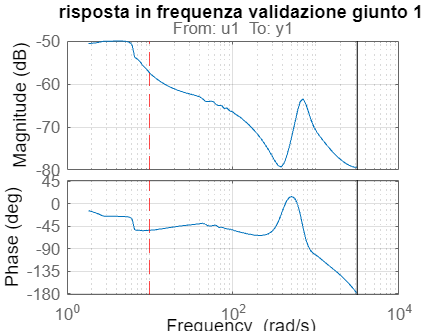

figure
subplot(1,1,1)
bode(frequency_response_validazione_g1)
title('risposta in frequenza validazione giunto 1')
hold on
h1 = get(gcf,'Children');
xline(h1(2),w0,'--r')
xline(h1(3),w0,'--r')
hold off
grid on

## Validazione

#### Giunto 1

    Confronto tra validazione e modello discreto e continuo 

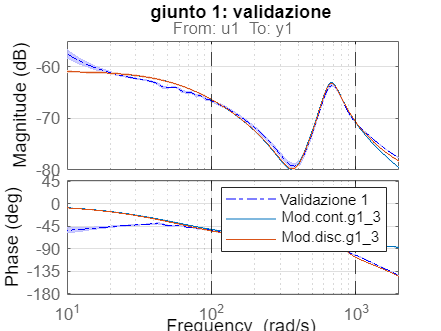

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(frequency_response_validazione_g1,'-.', bode_opts);
showConfidence(h,3)
hold on
bode(modello_continuo_g1_3rd, bode_opts)
bode(modello_discreto_g1_3rd, bode_opts)
h1 = get(gcf,'Children');
xline(h1(3),weight1_1,'--k')
xline(h1(3),weight1_2,'--k')
xline(h1(2),weight1_1,'--k')
xline(h1(2),weight1_2,'--k')
grid on
xlim([weight1_1/10 weight1_2*2])
title('giunto 1: validazione')
legend('Validazione 1','Mod.cont.g1_3','Mod.disc.g1_3')

Risposta in frequenza della validazione e identificazione

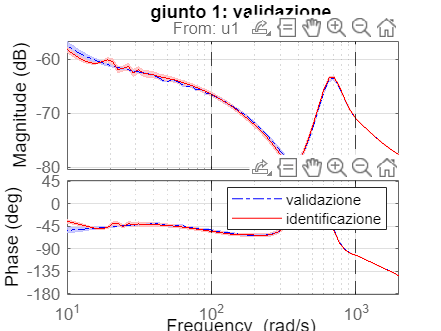

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(frequency_response_validazione_g1,'b-.', bode_opts);
showConfidence(h,3)
hold on
bode(frequency_response_identification_g1, bode_opts,'r')
h1 = get(gcf,'Children');
xline(h1(3),weight1_1,'--k')
xline(h1(3),weight1_2,'--k')
xline(h1(2),weight1_1,'--k')
xline(h1(2),weight1_2,'--k')
grid on
xlim([weight1_1/10 weight1_2*2])
title('giunto 1: validazione')
legend('validazione','identificazione')

hold off

Identificazione Vs validazione

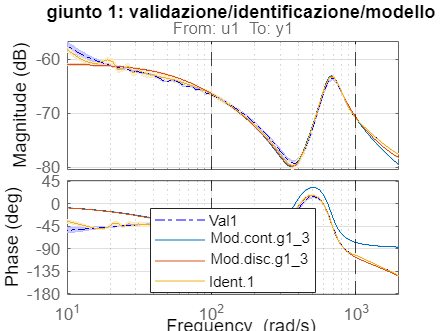

figure()
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(frequency_response_validazione_g1,'-.', bode_opts);
showConfidence(h,3)
hold on
bode(modello_continuo_g1_3rd, bode_opts)
bode(modello_discreto_g1_3rd, bode_opts)
bode(frequency_response_identification_g1)
h1 = get(gcf,'Children');
xline(h1(3),weight1_1,'--k')
xline(h1(3),weight1_2,'--k')
xline(h1(2),weight1_1,'--k')
xline(h1(2),weight1_2,'--k')
grid on
xlim([weight1_1/10 weight1_2*2])
title('giunto 1: validazione/identificazione/modello')
legend('Val1','Mod.cont.g1_3','Mod.disc.g1_3', 'Ident.1','Location','best')
hold off

save("..\file_mat_init\ide_giunto1.mat","modello_continuo_g1_3rd")
